%defaultDir = 'M:\Projects and Analysis\Papers\Development'; %change if in a different location
defaultDir = 'C:\Users\Travis\Desktop\Development Paper';
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['MRS2500 over development ISCs']);


%load P1_2 data
fileList = loadFileList(['.\Data\WT_MRS\P1_2\*\*_gfv_stats.mat']);

for i=1:size(fileList,1)
    s = load(fileList{i});
    cellS(i)= s.tempCell;
end

pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

pkstatBlock(6:7,3) = NaN;
ampstatBlock(6:7,3) = NaN;
intstatBlock(6:7,3) = NaN;

dim = [1.6 1.6];
compare3P(pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),conditions,'Events Per Minute',dim,[5 12]);

Unrecognized function or variable 'conditions'.

ylim([0 50]);
yticks(0:10:50);
export_fig('.\EPS Panels\P1_2_MRSfreq.eps');

compare3P(ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),conditions,'Mean Amp (pA)',dim,[5 12]);
ylim([0 1500]);
yticks(0:500:1500);
export_fig('.\EPS Panels\P1_2_MRSamp.eps');

compare3P(intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),conditions,'Charge Transfer (-pA*s)',dim,[5 12]);
ylim([0 1000]);
yticks(0:250:1000);
export_fig('.\EPS Panels\P1_2_MRSint.eps');


% One-way Anova for statistics
% p = anova1(pkstatBlock)
% [p,~,stats] = anova1(ampstatBlock)
% c = multcompare(stats)
% [p,~,stats]= anova1(intstatBlock)
% c = multcompare(stats)
rtbl = table([1:size(pkstatBlock,1)]',pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')

ans = 6×7 table
    Conditions_1    Conditions_2    Difference    StdErr    pValue      Lower     Upper 
    ____________    ____________    __________    ______    _______    _______    ______

         1               2             1.825      4.8453    0.92572    -13.042    16.692
         1               3              7.65      2.8693    0.08265    -1.1537    16.454
         2               1            -1.825      4.8453    0.92572    -16.692    13.042
         2               3             5.825      5.7227    0.59349    -11.734    23.384
         3               1             -7.65      2.8693    0.08265    -16.454    1.1537
         3               2            -5.825      5.7227    0.59349    -23.384    11.734


rtbl = table([1:size(pkstatBlock,1)]',ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')

ans = 6×7 table
    Conditions_1    Conditions_2    Difference    StdErr     pValue      Lower      Upper  
    ____________    ____________    __________    ______    ________    _______    ________

         1               2            430.75      126.58    0.033326      42.36      819.14
         1               3            239.69      77.998    0.049709    0.36944      479.01
         2               1           -430.75      126.58    0.033326    -819.14      -42.36
         2               3           -191.06       67.12    0.065853       -397       14.88
         3               1           -239.69      77.998    0.049709    -479.01    -0.36944
         3               2            191.06       67.12    0.065853     -14.88         397


rtbl = table([1:size(pkstatBlock,1)]',intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')

ans = 6×7 table
    Conditions_1    Conditions_2    Difference    StdErr     pValue      Lower     Upper 
    ____________    ____________    __________    ______    ________    _______    ______

         1               2            278.53      95.213    0.059687    -13.614    570.66
         1               3            158.54      54.131    0.059428    -7.5508    324.63
         2               1           -278.53      95.213    0.059687    -570.66    13.614
         2               3           -119.99       52.18     0.13184    -280.09    40.115
         3               1           -158.54      54.131    0.059428    -324.63    7.5508
         3               2            119.99       52.18     0.13184    -40.115    280.09


%load P7_8 data
fileList = loadFileList(['.\Data\WT_MRS\P7_8\*\*_gfv_stats.mat']);
clear cellS;
for i=1:size(fileList,1)
    s = load(fileList{i});
    cellS(i)= s.tempCell;
end

pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];
conditions = {'Baseline','MRS','Washout'}

conditions = 1×3 cell array
    {'Baseline'}    {'MRS'}    {'Washout'}


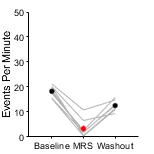

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.6 1.6];
compare3P(pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),conditions,'Events Per Minute',dim,[5 12]);
ylim([0 50]);
yticks(0:10:50);
export_fig('.\EPS Panels\P7_8_MRSfreq.eps');

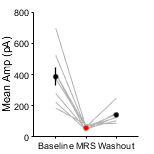


compare3P(ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),conditions,'Mean Amp (pA)',dim,[5 12]);
ylim([0 800]);
yticks(0:200:800);
export_fig('.\EPS Panels\P7_8_MRSamp.eps');

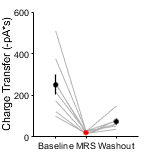


compare3P(intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),conditions,'Charge Transfer (-pA*s)',dim,[5 12]);
ylim([0 600]);
yticks(0:200:600);
export_fig('.\EPS Panels\P7_8_MRSint.eps');

% One-way Anova for statistics
[p,~,stats] = ranova(pkstatBlock)

Unrecognized function or variable 'ranova'.

rtbl = table([1:size(pkstatBlock,1)]',pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')

ans = 6×7 table
    Conditions_1    Conditions_2    Difference    StdErr       pValue       Lower      Upper 
    ____________    ____________    __________    _______    __________    _______    _______

         1               2            14.857       1.1488    0.00011665     11.119     18.595
         1               3            5.8286      0.95641     0.0040027     2.7165     8.9406
         2               1           -14.857       1.1488    0.00011665    -18.595    -11.119
         2               3           -9.0286       1.4217     0.0033306    -13.655    -4.4023
         3               1           -5.8286      0.95641     0.0040027    -8.9406    -2.7165
         3               2            9.0286       1.4217     0.0033306     4.4023     

rtbl = table([1:size(pkstatBlock,1)]',ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')

ans = 6×7 table
    Conditions_1    Conditions_2    Difference    StdErr     pValue      Lower      Upper 
    ____________    ____________    __________    ______    ________    _______    _______

         1               2             323.2      72.232     0.01496     88.168     558.24
         1               3            242.03      66.158    0.032787     26.757      457.3
         2               1            -323.2      72.232     0.01496    -558.24    -88.168
         2               3           -81.173      18.466    0.016076    -141.26    -21.085
         3               1           -242.03      66.158    0.032787     -457.3    -26.757
         3               2            81.173      18.466    0.016076     21.085     141.26


rtbl = table([1:size(pkstatBlock,1)]',intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')

ans = 6×7 table
    Conditions_1    Conditions_2    Difference    StdErr     pValue      Lower      Upper 
    ____________    ____________    __________    ______    ________    _______    _______

         1               2            228.07      54.425    0.019459      50.98     405.17
         1               3            175.43      52.571    0.045765     4.3697     346.49
         2               1           -228.07      54.425    0.019459    -405.17     -50.98
         2               3           -52.642      12.293    0.017856    -92.642    -12.641
         3               1           -175.43      52.571    0.045765    -346.49    -4.3697
         3               2            52.642      12.293    0.017856     12.641     92.642





c = multcompare(stats)
[p,~,stats] = anova1(ampstatBlock)
c = multcompare(stats)
[p,~,stats]= anova1(intstatBlock)
c = multcompare(stats)


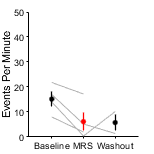

%load P11_12 data
fileList = loadFileList(['.\Data\WT_MRS\P11_12\*\*_gfv_stats.mat']);
clear cellS;
for i=1:size(fileList,1)
    s = load(fileList{i});
    cellS(i)= s.tempCell;
end

pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.6 1.6];
for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.6 1.6];
compare3P(pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),conditions,'Events Per Minute',dim,[5 12]);
ylim([0 50]);
yticks(0:10:50);
export_fig('.\EPS Panels\P7_8_MRSfreq.eps');

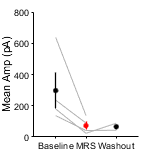


compare3P(ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),conditions,'Mean Amp (pA)',dim,[5 12]);
ylim([0 800]);
yticks(0:200:800);
export_fig('.\EPS Panels\P7_8_MRSamp.eps');

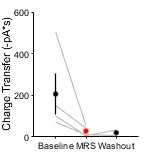


compare3P(intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),conditions,'Charge Transfer (-pA*s)',dim,[5 12]);
ylim([0 600]);
yticks(0:200:600);
export_fig('.\EPS Panels\P7_8_MRSint.eps');

% One-way Anova for statistics
[p,~,stats] = ranova(pkstatBlock)

rtbl = table([1:size(pkstatBlock,1)]',pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')
rtbl = table([1:size(pkstatBlock,1)]',ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')
rtbl = table([1:size(pkstatBlock,1)]',intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),'VariableNames',{'Group','meas1','meas2','meas3'});
meas = table([1 2 3]','VariableNames',{'Conditions'});
rm = fitrm(rtbl,'meas1-meas3~Group','WithinDesign',meas);
ranova(rm);
multcompare(rm,'Conditions')

'compare2P' is not found in the current folder or on the MATLAB path, but exists in:
    M:\Projects and Analysis\Papers\P2ry1\MATLAB Functions

Change the MATLAB current folder or add its folder to the MATLAB path.